load('Tire model/TTC data files/B1965run2.mat')

Inflation pressure of 12 psi goes from 1-19984

12 psi, 0 camber is 1-7495

1-1249

1250-2498

2499-3746

3747-4996

4997-6245

6246-7495

Group data:

n_data=size(ET);
scalefactor=0.6;
[loadlb,loadub] = groupdata(FZ(1250:7495),5,100,1249);

Fit Pacejka function to data

%for i=1:size(loadlb,1)
%    start = 0;
%    if (i>1)
%        start=loadub(i-1);
%    end
%    [SAlb,SAub]=groupdata(SA(loadlb(i):loadub(i)),3,0.19,start);
%    fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA
%    fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));
%end

C=zeros(10,3);
[SAlb,SAub]=groupdata(SA(loadlb(1):loadub(1)),3,0.19,0);
C(1,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


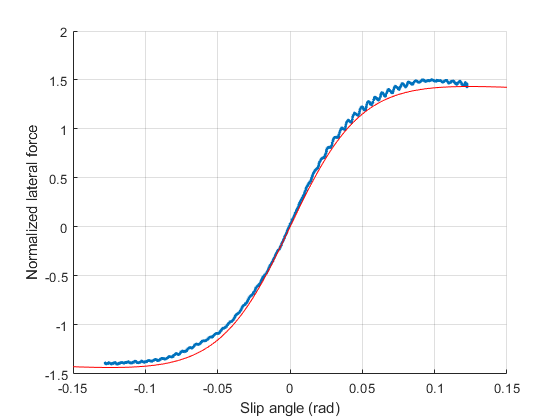


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(2,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

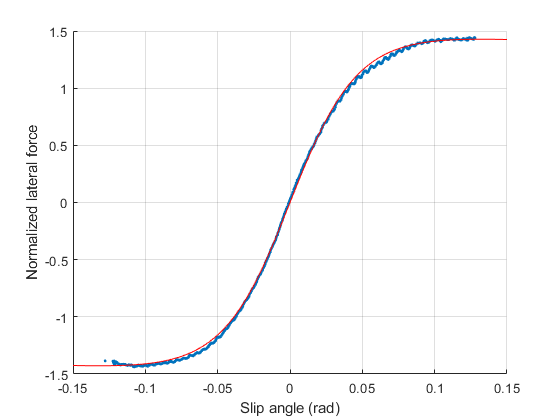


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(2):loadub(2)),3,0.19,loadub(1));
C(3,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

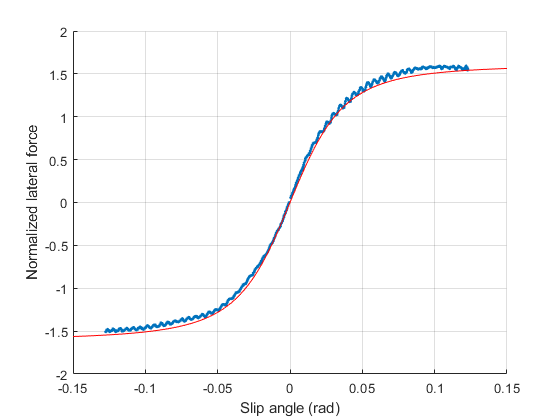


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(4,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

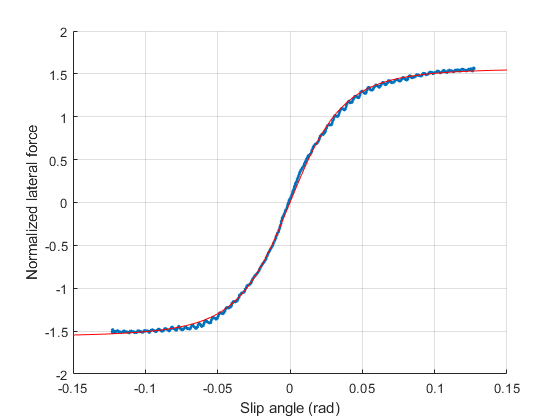


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(3):loadub(3)),3,0.19,loadub(2));
C(5,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

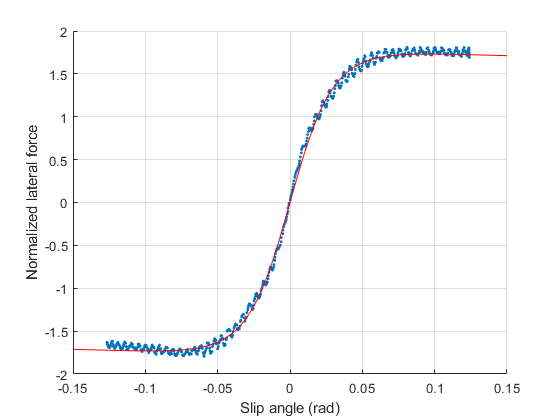


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(6,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

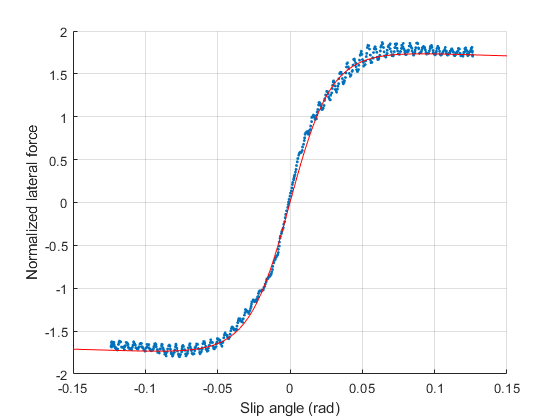


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(4):loadub(4)),3,0.19,loadub(3));
C(7,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

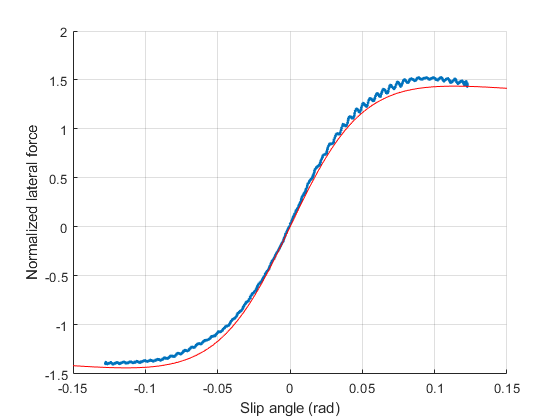


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


C(8,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));

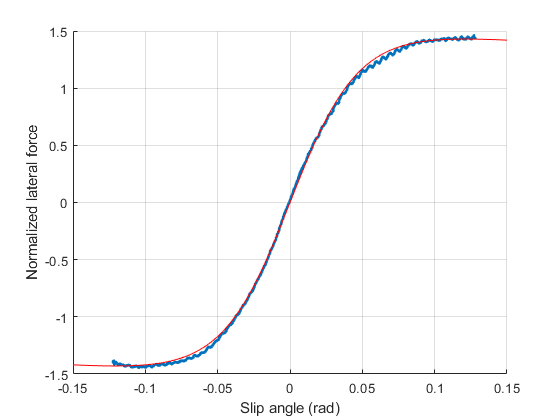


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



[SAlb,SAub]=groupdata(SA(loadlb(5):loadub(5)),3,0.19,loadub(4));
C(9,:) = fit([SA(SAlb(1):SAub(1));SA(SAlb(3):SAub(3))],[NFY(SAlb(1):SAub(1));NFY(SAlb(3):SAub(3))]); % Increasing SA

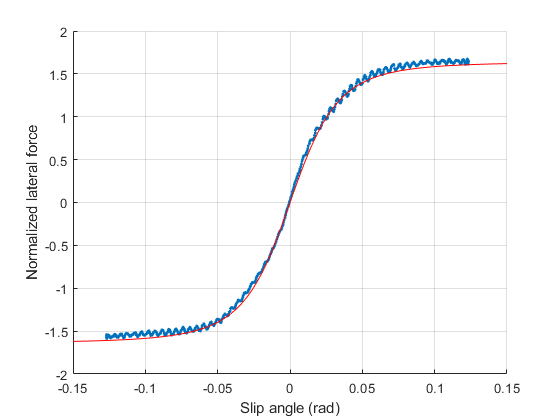


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


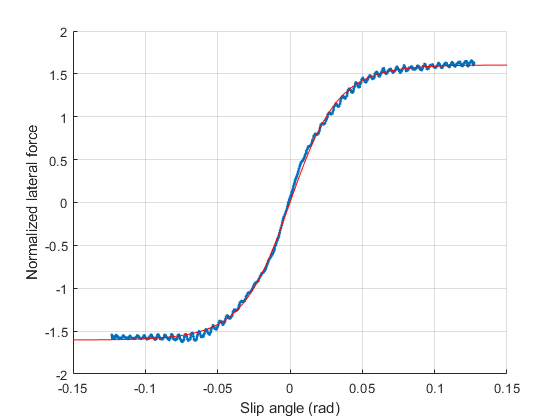

C(10,:) = fit(SA(SAlb(2):SAub(2)),NFY(SAlb(2):SAub(2)));


save('Tire model/pacejka_coefficients_lateral.mat',"C");

Stiffness coefficients:

% stiff=zeros(12,1);
% for j=1:12
%     stiff(j)=C(j,3)*C(j,2)*C(j,1)*(1-C(j,4));
% end
% save('lateral_stiffness.mat',"stiff");

Find the average value in each load group:

loads = [
    mean(FZ(loadlb(1):loadub(1))) ...
    mean(FZ(loadlb(2):loadub(2))) ...
    mean(FZ(loadlb(3):loadub(3))) ...
    mean(FZ(loadlb(4):loadub(4))) ...
    mean(FZ(loadlb(5):loadub(5))) ...
    ]

loads = 	1.0e+03 *

   -0.8799   -0.6574   -0.2092   -1.0965   -0.4331


Load and SA step size:

d_load = 20;
d_SA = 0.002;

Take sample points of each fitted curve (curve is in row):

SA_x = 0:d_SA:1;
n_SA = length(SA_x);
sample_points = pacejka(C,SA_x);

Split sample points into increasing and decreasing SA:

sample_points_inc = [
    sample_points(1,:); ...
    sample_points(3,:); ...
    sample_points(5,:); ...
    sample_points(7,:); ...
    sample_points(9,:); ...
    ]

sample_points_inc =          0    0.0616    0.1230    0.1840    0.2443    0.3039    0.3624    0.4197    0.4758    0.5303    0.5833    0.6345    0.6840    0.7316    0.7773    0.8210    0.8628    0.9026    0.9404    0.9762    1.0101    1.0422    1.0724    1.1007    1.1274    1.1524    1.1758    1.1976    1.2180    1.2369    1.2546    1.2710    1.2862    1.3002    1.3132    1.3252    1.3363    1.3464    1.3558    1.3643    1.3722    1.3793    1.3859    1.3918    1.3972    1.4021    1.4065    1.4104    1.4140    1.4171
         0    0.0815    0.1625    0.2423    0.3205    0.3966    0.4701    0.5407    0.6083    0.6725    0.7332    0.7905    0.8443    0.8947    0.9417    0.9854    1.0261    1.0639    1.0989    1.1313    1.1613    1.1890    1.2147    1.2384    1.2604    1.2807    1.2995    1.3169    1.3330    1.3480    1.3619    1.3748    1.3868    1.3979    1.4084    1.4181    1.4271    1.4356    1.4435    1.4509    1.4579    1.4644    1.4705    1.4763    1.4817    1.4868    1.4916    1.496

sample_points_dec = [
    sample_points(2,:); ...
    sample_points(4,:); ...
    sample_points(6,:); ...
    sample_points(8,:); ...
    sample_points(10,:); ...
    ]

sample_points_dec =          0    0.0635    0.1267    0.1894    0.2514    0.3125    0.3724    0.4310    0.4881    0.5435    0.5971    0.6488    0.6985    0.7462    0.7917    0.8352    0.8765    0.9156    0.9527    0.9877    1.0207    1.0517    1.0808    1.1081    1.1336    1.1574    1.1797    1.2004    1.2197    1.2376    1.2542    1.2696    1.2838    1.2970    1.3091    1.3204    1.3307    1.3402    1.3490    1.3571    1.3644    1.3712    1.3774    1.3831    1.3882    1.3929    1.3972    1.4011    1.4046    1.4077
         0    0.0825    0.1645    0.2453    0.3245    0.4016    0.4762    0.5479    0.6165    0.6818    0.7436    0.8018    0.8565    0.9077    0.9554    0.9999    1.0411    1.0793    1.1146    1.1473    1.1774    1.2052    1.2307    1.2543    1.2760    1.2960    1.3144    1.3313    1.3470    1.3614    1.3746    1.3869    1.3982    1.4087    1.4183    1.4273    1.4356    1.4433    1.4504    1.4570    1.4632    1.4689    1.4742    1.4792    1.4838    1.4881    1.4921    1.495

Fit a 4-th order polynomial to each column of points (load sensitivity at each SA):

poly_coeff_inc = zeros(3,n_SA);
for i = 1:n_SA
    poly_coeff_inc(:,i) = polyfit(loads,sample_points_inc(:,i),2);
end
poly_coeff_dec = zeros(3,n_SA);
for i = 1:n_SA
    poly_coeff_dec(:,i) = polyfit(loads,sample_points_dec(:,i),2);
end

Populate with extra load values in between the 5 given:

loadbounds = [-1200 0];
load_y = (loadbounds(1):d_load:loadbounds(2))';
n_load = length(load_y);
lat_coeff_inc = zeros(n_load,n_SA);
for j = 1:n_SA
    lat_coeff_inc(:,j) = polyval(poly_coeff_inc(:,j),load_y);
end
lat_coeff_dec = zeros(n_load,n_SA);
for j = 1:n_SA
    lat_coeff_dec(:,j) = polyval(poly_coeff_dec(:,j),load_y)';
end

Plot on a heat map:

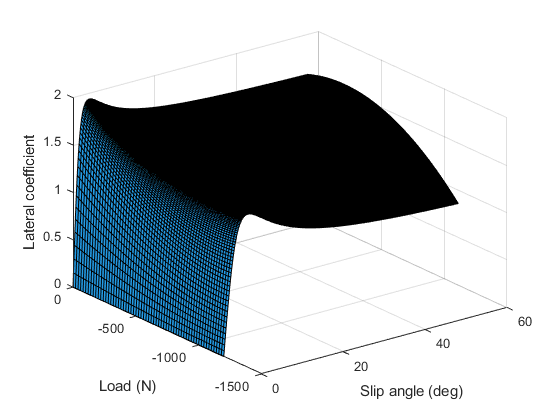

surfl(ones(n_load,1)*rad2deg(SA_x), ...
    load_y*ones(1,n_SA), ...
    lat_coeff_inc);
xlabel('Slip angle (deg)')
ylabel('Load (N)')
zlabel('Lateral coefficient')


save('Tire model/lateral_force_lut.mat', ...
    'lat_coeff_inc', ...
    'lat_coeff_dec', ...
    'SA_x', ...
    'load_y');

## Functions

Pacejka function:

function y = pacejka(C,sigma)
    sigma = ones(size(C,1),1)*sigma;
    y=(C(:,3)*ones(1,size(sigma,2))).*sin((C(:,2)*ones(1,size(sigma,2))).*atan(atan((C(:,1)*ones(1,size(sigma,2))).*sigma)));
end

Fit curve for a single vertical load group:

function C = fit(alpha_unscaled,mu_unscaled)
hold off
scalefactor=0.6;
alpha=alpha_unscaled*scalefactor;
alpha=deg2rad(alpha);
sigma_y=tan(alpha);
mu=mu_unscaled*scalefactor;
scatter(alpha,mu,5,'filled')
hold on
lb=-inf*ones(3,1);
ub=inf*ones(3,1);
C0=[1,1,1];
options=optimoptions('lsqcurvefit', ...
    'MaxFunctionEvaluations',1000, ...
    "Algorithm","levenberg-marquardt");
[Cfinal,~,~,~,~] = lsqcurvefit(@pacejka,C0,sigma_y,mu,lb,ub,options);
x=linspace(-0.15,0.15,100);
plot(x,pacejka(Cfinal,tan(x)),'red')
xlabel('Slip angle (rad)')
ylabel('Normalized lateral force')
grid on
hold off
C=Cfinal;
end

Grouping data:

function [lb,ub] = groupdata(data,n,range,start)
    lb=zeros(n,1);
    ub=zeros(n,1);
    lb(1)=1;
    x = 0;
    for i=1:n
        if i>1
            lb(i)=ub(i-1)+1;
        end
        while 1
            x=x+1;
            if (x == size(data,1)) || (abs(data(x) - data(x+1)) > range)
                ub(i)=x;
                break
            end
        end
    end
    lb=lb+start*ones(n,1);
    ub=ub+start*ones(n,1);
end